# **디지털신호처리 ****HW#2**

Due date : 2021.12.22. 23:59

**이름**** :서원형    **

**학번**** :201716201**

아래 문제에 대하여 MATLAB으로 구현하고 mlx파일을 본인의 Github에 업로드 하고 링크 주소를 적으세요.

**Repository 링크 : https://github.com/won-hyeong-seo/DSP/blob/main/HW2_201716201_seowonhyeong.mlx**

1. 이산 비주기 신호 $x\left\lbrack n\right\rbrack =\left\lbrace \underset{\uparrow }{1} ,2,2,1\right\rbrace$에 대하여 다음을 구하라.

1) 4점 DFT 및 IDFT를 수행하라. 그리고 DFT의 결과를 DTFT와 비교하라. 

%4점 DFT
x = [1, 2, 2, 1];
N = 4;
n = 0 : 3; k = 0 : 500; w = (pi/500)*k;
DTFT = x * (exp(-j*pi/250)) .^ (n'*k);
X = dft(x,N);
magX = abs(X), phaX = angle(X)*180/pi

magX =     6.0000    1.4142    0.0000    1.4142


phaX =          0 -135.0000  -90.0000  135.0000


%IDFT
idftx = idft(X, N);
magidtfx = abs(idftx), phaidtfx = angle(idftx)*180/pi

magidtfx =      1     2     2     1


phaidtfx = 	1.0e+-13 *

   -0.1607   -0.0230    0.0230    0.1607


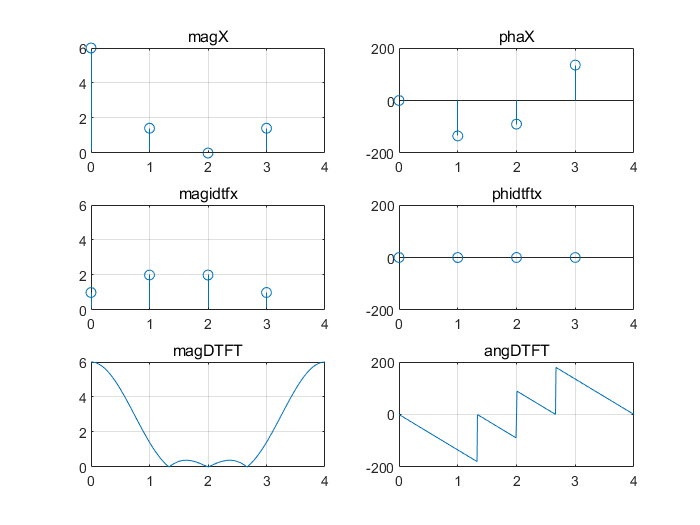

magDTFT = abs(DTFT); angDTFT = angle(DTFT)/pi*180;

figure(1)
subplot(3,2,1); stem(n, magX); axis([0, 4, 0, 6]);title('magX'); grid on
subplot(3,2,2); stem(n, phaX); axis([0, 4, -200, 200]);title('phaX'); grid on
subplot(3,2,3); stem(n, magidtfx); axis([0, 4, 0, 6]); title('magidtfx'); grid on
subplot(3,2,4); stem(n, phaidtfx); axis([0, 4, -200, 200]); title('phidtftx'); grid on
subplot(3,2,5); plot(k/500*4,magDTFT); title('magDTFT'); grid on
subplot(3,2,6); plot(k/500*4,angDTFT); title('angDTFT'); grid on

2) 영 채우기를 시행하여 같은 신호에 대해 16점 DFT 및 IDFT를 수행하라.

x = [1, 2, 2, 1, zeros(1, 12)];
n = 0:15; N = 16;
DFT = dft(x, N); IDFT = idft(DFT, N);
magDFT = abs(DFT), angDFT = angle(DFT)

magDFT =     6.0000    5.5861    4.4609    2.9357    1.4142    0.2607    0.3170    0.3308    0.0000    0.3308    0.3170    0.2607    1.4142    2.9357    4.4609    5.5861


angDFT =          0   -0.5890   -1.1781   -1.7671   -2.3562   -2.9452   -0.3927   -0.9817    1.5708    0.9817    0.3927    2.9452    2.3562    1.7671    1.1781    0.5890


magIDFT = abs(IDFT), angIDFT = angle(IDFT)

magIDFT =     1.0000    2.0000    2.0000    1.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


angIDFT =     0.0000    0.0000   -0.0000   -0.0000   -0.5432   -0.8918   -0.8533   -1.2178   -1.3068   -1.5708   -1.5708   -1.9401   -2.0950   -2.3011   -2.5419   -2.7523


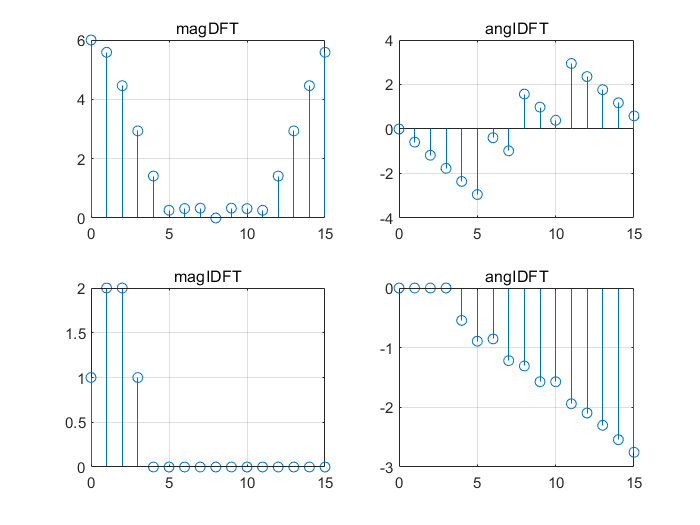

figure(2)
subplot(2,2,1); stem(n, magDFT); title('magDFT'); grid on
subplot(2,2,2); stem(n, angDFT); title('angIDFT'); grid on
subplot(2,2,3); stem(n, magIDFT); title('magIDFT'); grid on
subplot(2,2,4); stem(n, angIDFT); title('angIDFT'); grid on

2. (P5.2) DFS의 정의를 사용하여 다음 주기 신호의 DFS 계수를 구하고, MATLAB을 사용하여 검증하라.

1) $\tilde{x_1 } \left(n\right)=\left\lbrace 4,1,-1,1\right\rbrace ,N=4$

%정의 사용
N = 4; n = 0 : 1 : N-1; k = 0 : 1 : N-1;
x = [4, 1, -1, 1];
Xk = x * exp(-j * 2 * pi / N * n' * k)

Xk =    5.0000 + 0.0000i   5.0000 + 0.0000i   1.0000 - 0.0000i   5.0000 + 0.0000i


%함수 사용
N = 4; x = [4, 1, -1, 1];
Xk = dfs(x,N)

Xk =    5.0000 + 0.0000i   5.0000 + 0.0000i   1.0000 - 0.0000i   5.0000 + 0.0000i


2) $\tilde{x_2 } \left(n\right)=\left\lbrace 1,0,-1,-1,0\right\rbrace ,N=5$

%정의 사용
N = 5; n = 0 : 1 : N-1; k = 0 : 1 : N-1;
x = [1, 0, -1, -1, 0];
Xk = x * exp(-j * 2 * pi / N * n' * k)

Xk =   -1.0000 + 0.0000i   2.6180 + 0.0000i   0.3820 - 0.0000i   0.3820 - 0.0000i   2.6180 + 0.0000i



%함수 사용
N = 5; x = [1, 0, -1, -1, 0];
Xk = dfs(x,N)

Xk =   -1.0000 + 0.0000i   2.6180 + 0.0000i   0.3820 - 0.0000i   0.3820 + 0.0000i   2.6180 + 0.0000i


3.  (P5.10) 아래와 같이 주어진 유한 길이 신호를 고려하자.


$$x\left(n\right)=\left\lbrace \begin{array}{ll}
{\textrm{sinc}}^2 \left\lbrace \frac{\left(n-50\right)}{2}\right\rbrace  & 0\le n\le 100\\
0 & \textrm{otherwise}
\end{array}\right.$$


1) x(n)의 DFT X(k)를 구하라. (stem 함수를 사용하여) 그것의 크기 및 위상 그래프를 그려라. 

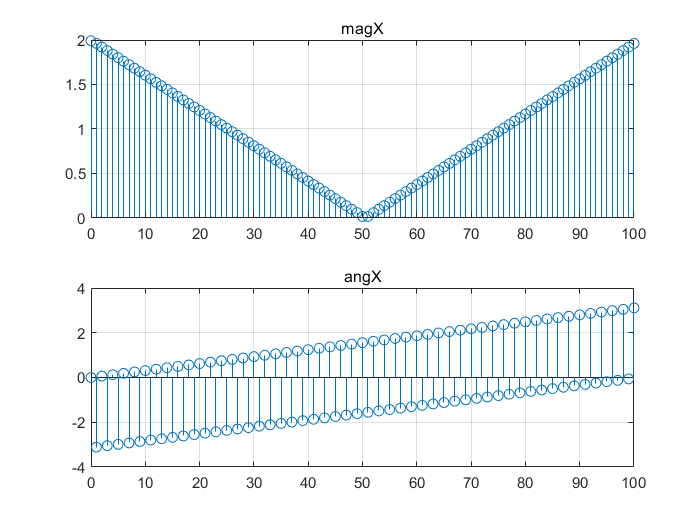

n = 0 : 100; N = 101; 
x = (sinc((n - 50) / 2)) .^ 2;
X = dft(x,N);
magX = abs(X); angX = angle(X);
figure(3)
subplot(2,1,1); stem(n, magX); title('magX'); grid on
subplot(2,1,2); stem(n, angX); title('angX'); grid on

2) MATLAB을 사용하여 x(n)의 DTFT $X\left(e^{j\omega } \right)$의 크기 및 위상 그래프를 그려라.

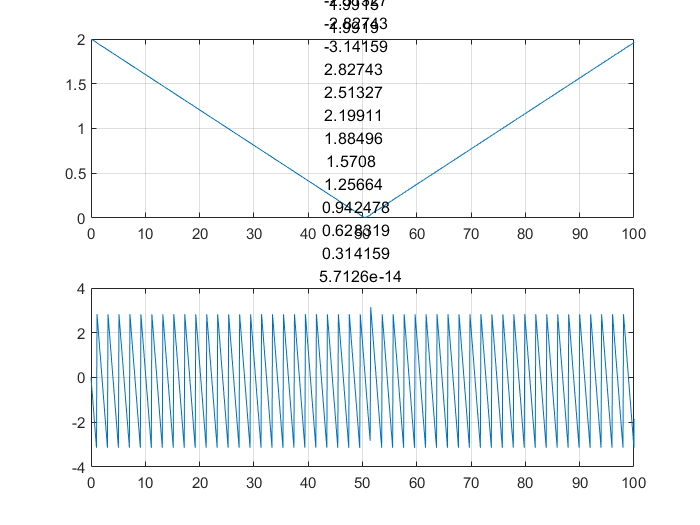

k = 0 : 0.5 : 500; w = (pi / 500) * k;
n = 0 : 100;
x = (sinc((n - 50) / 2)) .^ 2;
DTFT = x * (exp(-j*pi/250)) .^ (n'*k);
magDTFT = abs(DTFT); angDTFT = angle(DTFT);

figure(4)
subplot(2,1,1); plot(w/pi*101, magDTFT); axis([0, 100, 0, 2]); title(magDTFT); grid on
subplot(2,1,2); plot(w/pi*101, angDTFT); axis([0, 100, -4, 4]); title(angDTFT); grid on

3) 위 DFT는 $X\left(e^{j\omega } \right)$의 샘플링된 변형임을 검증하라. hold 함수 (hold on;) 를 사용해서 두 그래프를 합치도록 한다.

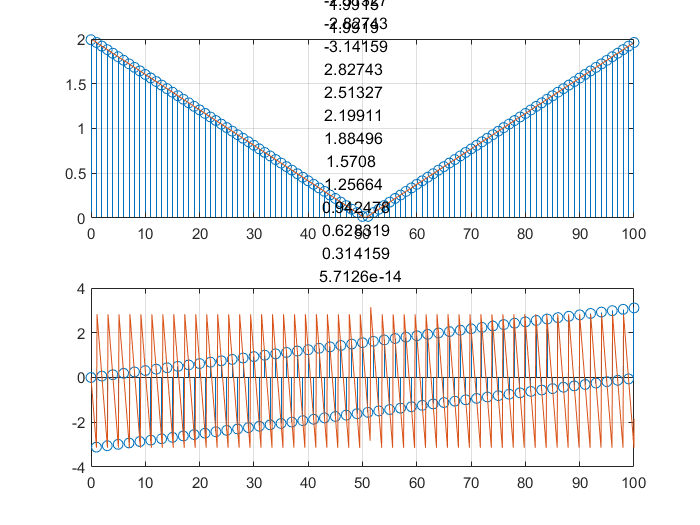

n = 0 : 100; N = 101; 
x = (sinc((n - 50) / 2)) .^ 2;
X = dft(x,N);
magX = abs(X); angX = angle(X);

k = 0 : 0.5 : 500; w = (pi / 500) * k;
DTFT = x * (exp(-j*pi/250)) .^ (n'*k);
magDTFT = abs(DTFT); angDTFT = angle(DTFT);

figure(5)
subplot(2,1,1); stem(n, magX); hold on; plot(w/pi*101, magDTFT);
axis([0, 100, 0, 2]); title(magDTFT); hold off; grid on

subplot(2,1,2); stem(n, angX); hold on; plot(w/pi*101, angDTFT); 

axis([0, 100, -4, 4]);title(angDTFT); hold off; grid on

4) DFT $X\left(k\right)$로부터 DTFT $X\left(e^{j\omega } \right)$를 재구성할 수 있는가? 가능하다면, 재구성에 필요한 보간 공식을 구하라. 가능하지 않다면, 그 이유를 기술하라.

        가능하다. 


$$\Phi \left(w\right)=\frac{\sin \left(\frac{\mathrm{wN}}{2}\right)}{\mathrm{Nsin}\left(\frac{w}{2}\right)}e^{-\mathrm{jw}\left(\frac{N-1}{2}\right)} =\frac{\sin \left(\frac{101w}{2}\right)}{101\sin \left(\frac{w}{2}\right)}e^{-\mathrm{j50w}}$$


function [Xk] = dft(xn, N)
n = 0 : N-1;
k = 0 : N-1;
WN = exp(-j*2*pi/N);
nk = n'*k;
WNnk = WN .^ nk;
Xk = xn * WNnk;
end

function [xn] = idft(Xk, N)
n = 0 : N-1;
k = 0 : N-1;
WN = exp(-j*2*pi/N);
nk = n'*k;
WNnk = WN .^ (-nk);
xn = (Xk * WNnk)/N;
end

function [Xk] = dfs(xn,N)
n = 0:N-1; k = 0 : N-1;
WN = exp(-j * 2 * pi / N); nk  = n' * k;
WNnk = WN .^ nk;
Xk = xn * WNnk;
end

function [xn] = idfs(Xk, N)
n = 0:N-1; k = 0 : N-1;
WN = exp(-j * 2 * pi / N); nk  = n' * k;
WNnk = WN .^ (-nk);
xn = (Xk * WNnk)/N;
end